## Ann Fiegel - Class Project Part 4

Module 2, Project Bank Question 6

Objective: Simulate voltage response of an RC circuit during charging and discharging. 

Core Tasks:

Implement time-stopped voltage update

Compare different resistance or capacitance values

Key Deliverables: Voltage curves and parameter sensitivity discussion

For this model it is assumed that the resistor has a value 220 ohms, and the capacitor of capacitance of 1F

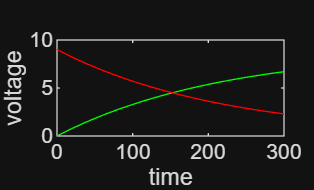

t = 0:5:300; % time range for model

R = 220; % resistance of resistor in ohms

C = 1; % capacitance in farad 

function Vc = v(t,R,C) % function for voltage change while charging

Vc = 9*(1 - exp((-1.*t)./R*C));

end % end of function 

function Vd = f(t,R,C) % function for voltage decay

Vd = 9*(exp(-1*t./R*C));

end % end of function 

Vc = v(t,R,C); % calculate voltage while charging

Vd = f(t,R,C); % calculate voltage decay

plot(t, Vc, 'g-'); % plot voltage while charging
hold on; % making both plots on the same graph
plot(t, Vd, 'r-'); % plotting voltage decay
xlabel('time'); % labeling x axis
ylabel('voltage'); % labeling y axis
hold off; % hold on placing everything on the same graph off